## **Ejemplo de Matlab**

rng('default'); % For reproducibility
n = 20;
X = [randn(n,2)*0.5+3;
    randn(n,2)*0.5;
    randn(n,2)*0.5-3];

[~,V_temp,D_temp] = spectralcluster(X,5);

D_temp

D_temp =    -0.0000
   -0.0000
   -0.0000
    0.0876
    0.1653


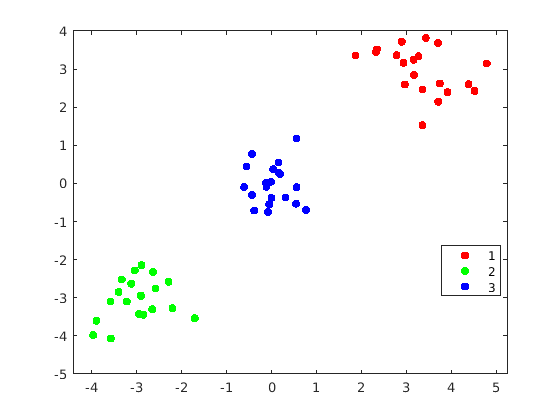

[a,b] = find(D_temp<1e-3);

k = sum(b);
[idx1,V,D] = spectralcluster(X,k);
gscatter(X(:,1),X(:,2),idx1);

## Clusterización con un ejemplo de nichos

----Reading layers----


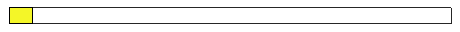

Elapsed time is 15.634655 seconds.


addpath Tool/VirtualSpeciesFunctions/
addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Finding clusters----
3 clusters identified


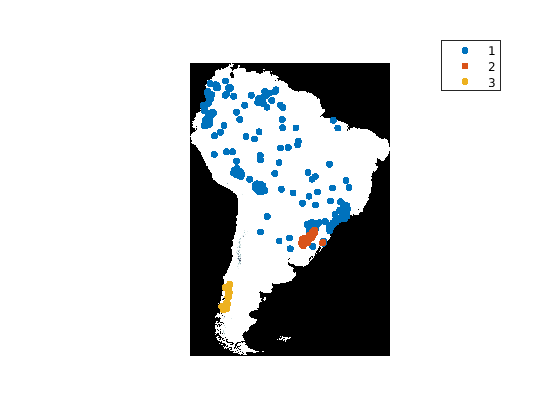

----Finding correlation----
Elapsed time is 2.245871 seconds.
----Creating predictors----
----Finding correlation----
Elapsed time is 2.579750 seconds.
----Creating predictors----
----Finding correlation----
Elapsed time is 2.953294 seconds.
----Creating predictors----
Elapsed time is 2.973370 seconds.
¡All done!


load("Clustering/T500.mat")
% load("Clustering/T.mat")

data1 = bnm_prep(T, Dimensions, false, 0.7);

----Modeling----
-Model 1
-Model 2
-Model 3


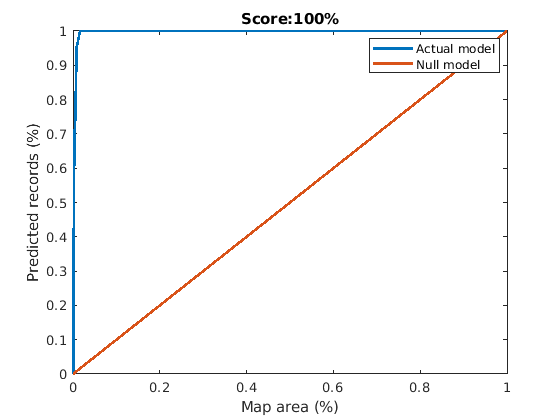

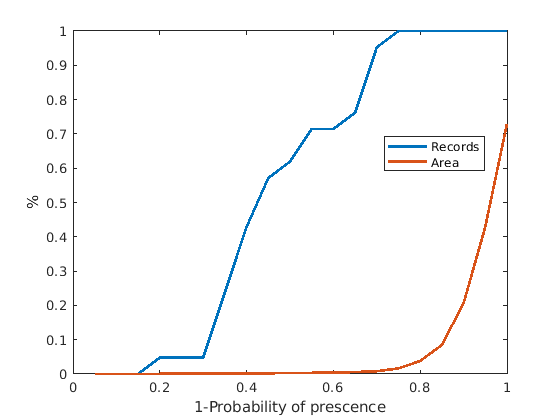

Elapsed time is 3.722243 seconds.


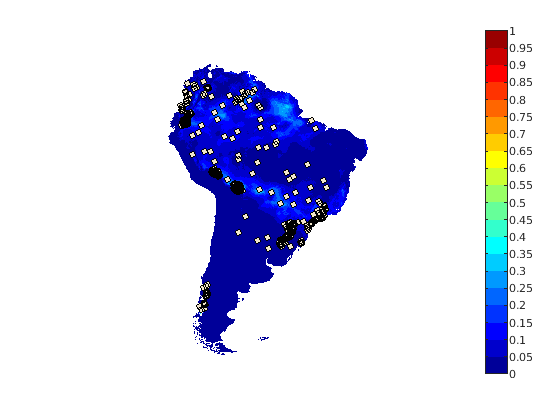

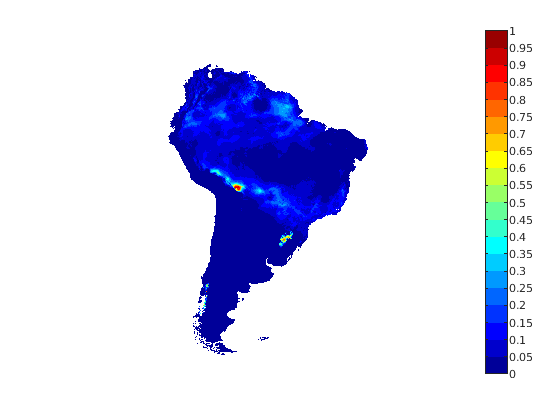

        % modeling, save Metric
data = bnm_modeling(data1, '', true); 

% load("Clustering/T_bio500.mat")
% load("Clustering/T_bio.mat")

X = table2array(T(:,4:22));

Variable index exceeds table dimensions.

[~,V_temp,D_temp] = spectralcluster(X,10,'Distance',"mahalanobis");

D_temp

Obtener orden de magnitud

    n = floor(log(abs(D_temp))./log(10))

n =    -11
   -12
   -12
   -13
   -13
   -25
   -26
   -26
   -26
   -26


    INF = isinf(n);
    n(INF) = 0;
    
    % find optmial number of clusters
    k = find(n <= min(n) + 5);
    k = length(k) + sum(INF)

k = 5

[idx1,V,D] = spectralcluster(X,3,'Distance',"mahalanobis");

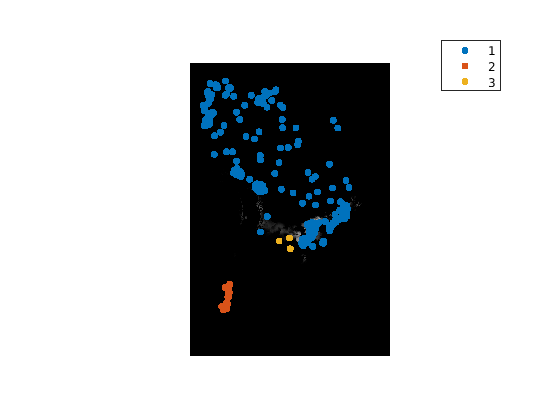

figure
colormap(gray(256))
geoshow(data.Map,Dimensions.R,'DisplayType','texturemap')
hold on

load carsmall
color = lines(6); % Generate color values

gscatter(T.LONG,T.LAT, idx1,color(1:6,:));
hold on
axis off